## **CYKLY UHELNÝCH TEPELNÝCH ELEKTRÁREN - RANKIN-CLAUSIŮV CYKLUS S PŘEHŘEVEM PÁRY**

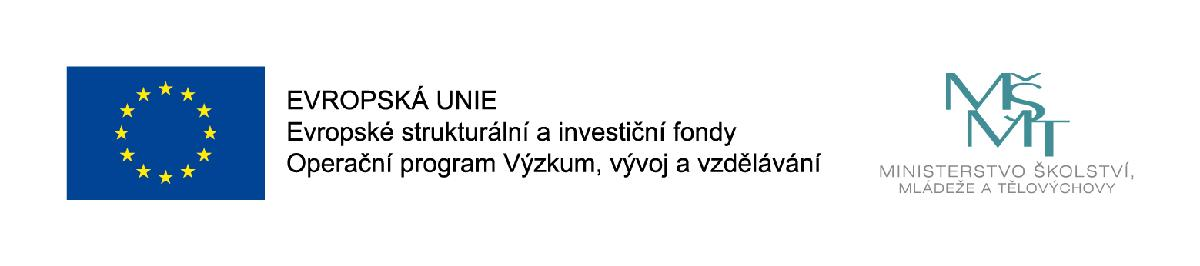

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

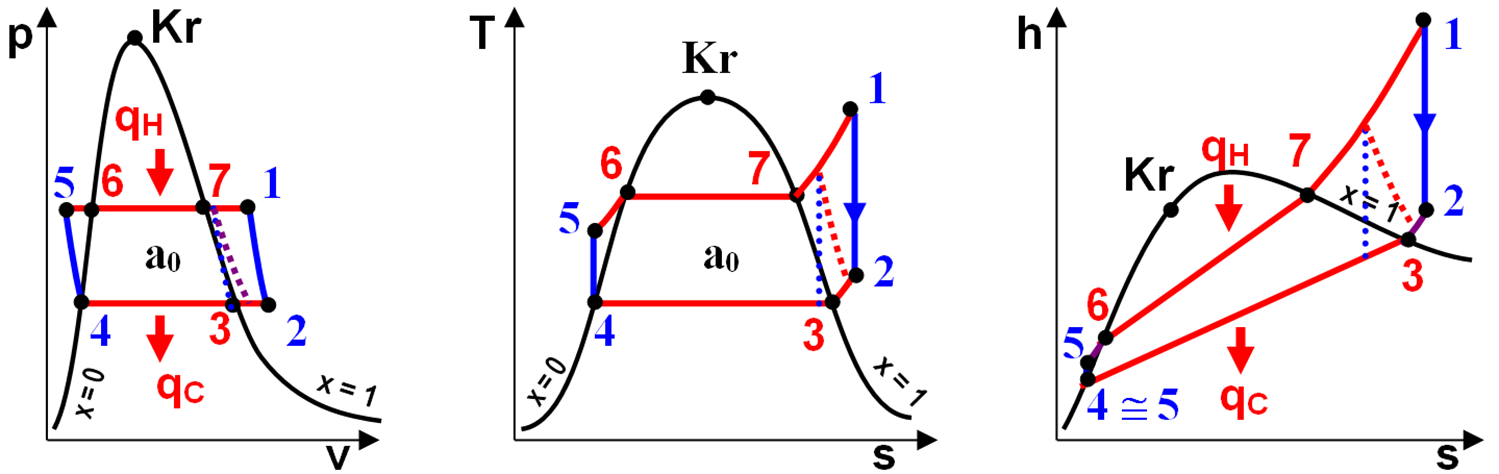

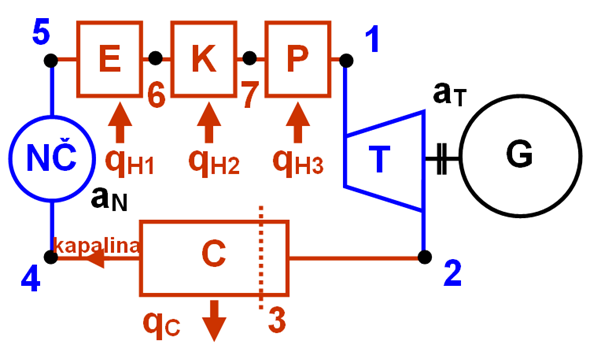

V parním kotli se ohřívá voda (kondenzát) ze stavu 5 při konstantním tlaku *p *na bod varu 6 a odpařuje se při konstantníteplotě na mez sytosti*. *Sytá pára proudí z kotle do přehříváku páry 7*, *kde se přehřeje (stav 1). Přehřátá pára je přiváděna do parní turbíny*, *kde adia­batickou expanzí na stav 2 koná práci. Z turbíny proudí zpravidla již mokrá pára do kondenzátoru*, *kde zkapalní*. *Kondenzát je pak dopraven napáječkou *NČ *do parního kotle.

Při kompresi vody předpokládáme, že voda je nestlačitelná a její objem se teplotou nezvětšuje.

Užitečná práce parního zařízení je dána rozdílem prací parní turbíny a na­páječky. Při nižších tlacích je práce napáječky proti práci dodané parní turbínou malá, takže za teoretickou práci parního zařízení uvažuje práce turbíny.

Při výpočtu účinnosti celého zařízení se však spotřeba energie napáječkou musí uvažovat, i když má svůj vlastní pohon, nezávislý na parní turbíně. Nepříznivý vliv napáječky roste se stoupajícím tlakem vyráběné páry.

Ohřívání napájecí vody se děje podél izobary, kterou při nižších tlacích můžeme ztotožnit s levou mezní křivkou. Ve skutečnosti, jak bylo již uvedeno v termodynamice par, jde izobara nad levou mezní křivkou, což znamená, že teplo potřebné k ohřátí napájecí vody bude při téže počáteční teplotě vyšší.


$$\[{q_H} = {h_1} - {h_5}\]$$



$$\[{q_C} = {h_4} - {h_2}\]$$



$$\[{a_T} = {h_1} - {h_2}\]$$



$$\[{a_N} = v \cdot ({p_4} - {p_5})\]$$



$$
\[{\eta _t} = \frac{{{a_T} - \left| {{a_N}} \right|}}{{{q_H}}} = \frac{{{a_O}}}{{{q_H}}} = \frac{{({h_1} - {h_2}) + \left( {{h_4} - {h_5}} \right)}}{{{h_1} - {h_5}}}\]$$


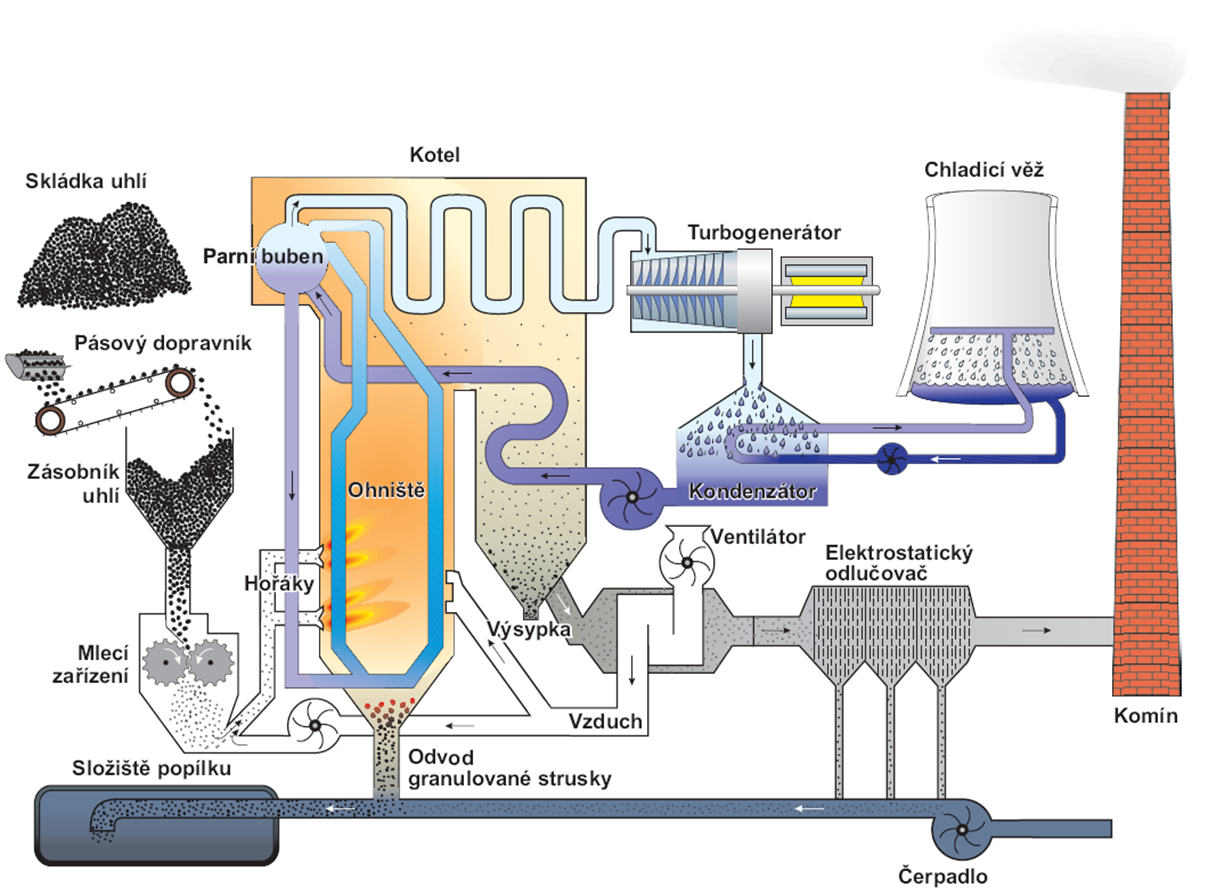

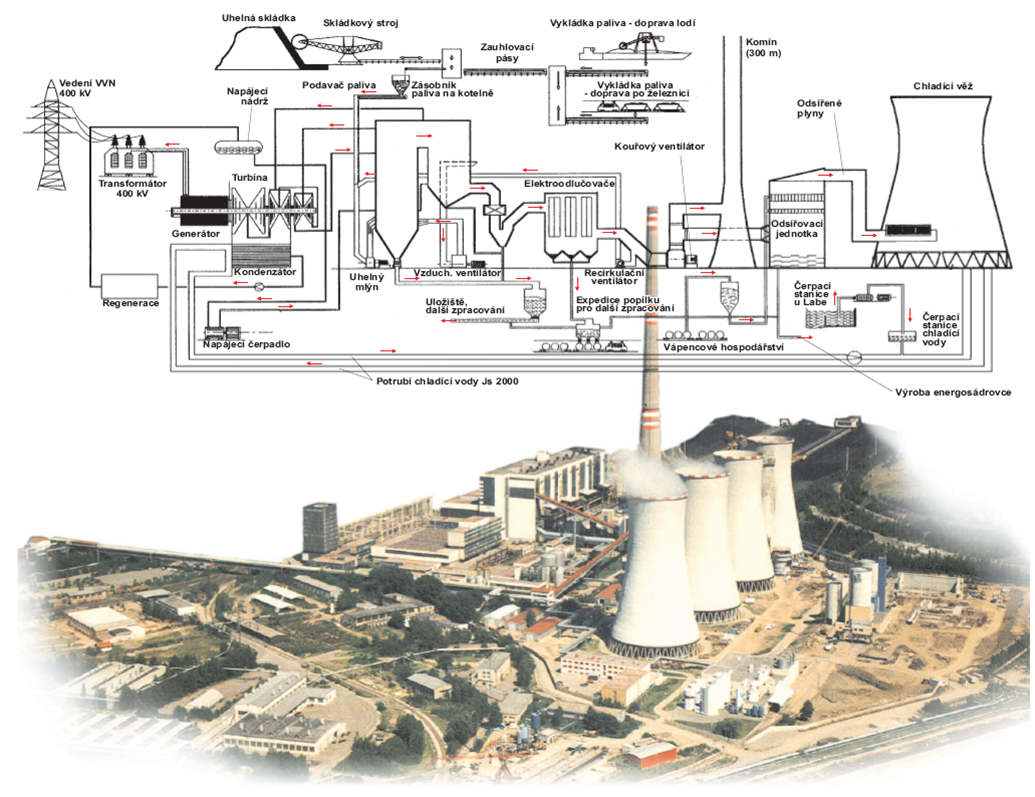

### Příklad RANKIN-CLAUSIUV CYKLUS

clear,clc,close all;

Uhelná tepelná elektrárna pacuje podle Rankin-Clausiova cyklu s přehřevem páry. Maximální tlak a teplota páry v přehříváku jsou 24 MPa a 680 °C. Tlak v kondenzátoru je 0.05 MPa. Napájecí čerpladlo dodává do kotle 100 ks/s vody. Určete přivedené a odvedené teplo, termickou účinnost a výkon bloku. Zakreslete cyklus v T-s diagramu.

mh = 100.0;     % kg/s
pmaxMPa = 12.0; % MPa
pminMPa = 0.05; % MPa
tmaxC = 560;    % °C

## Výpočet

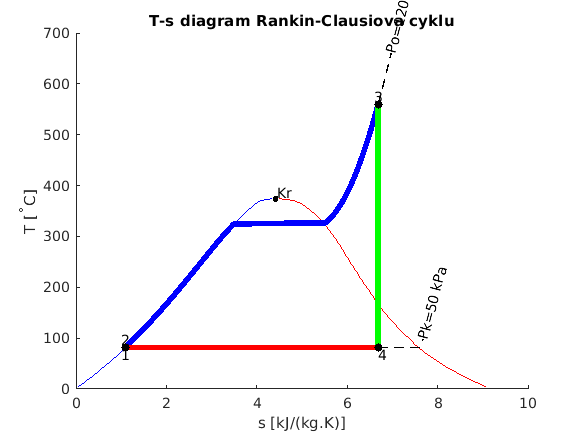

p=[0,0,0,0];
t=[0,0,0,0];
s=[0,0,0,0];
h=[0,0,0,0];
p(2)=pmaxMPa;   % input('Zadej tlak ohřevu [MPa]:');
p(1)=pminMPa;   % input('Zadej tlak kondenzace [MPa]:');
t(3)=tmaxC;     % input('Zadej maximalni teplotu páry na vstupu do turbíny [C]:');
p=10*p;
p(3)=p(2);
p(4)=p(1);

% určení neznámých veličin
t(1)=XSteam('Tsat_p',p(1));
s(1)=XSteam('sL_p',p(1));
h(1)=XSteam('hL_p',p(1));
s(2)=s(1);
t(2)=XSteam('T_ps',p(2),s(2));
s(3)=XSteam('s_pT',p(3),t(3));
s(4)=s(3);
h(4)=XSteam('h_ps',p(4),s(3));
h(3)=XSteam('h_pT',p(3),t(3));
t(4)=XSteam('T_ph',p(4),h(4));
h(2)=XSteam('h_ps',p(2),s(1));

% měrná práce turbíny
at=h(3)-h(4);
Pt = at * mh;

% měrná práce napáječky
an=h(2)-h(1);
Pn = an * mh;

% měrná práce cyklu
a0=at-an;
P = a0 * mh;

% přivedené teplo
qh=h(3)-h(2);
Qh = qh * mh;

% odvedené teplo
qc=h(1)-h(4);
Qc = qc * mh;

% termická účinnost oběhu
n=abs(a0)/qh;

% vykreslení grafu
figure;
hold on;

% vykreslení čar syté kapaliny a páry
vekT = linspace(0,800,200);
svyp = arrayfun(@(x) XSteam('sV_T',x),vekT);
skap = arrayfun(@(x) XSteam('sL_T',x),vekT);
plot(svyp,vekT,'r-')
plot(skap,vekT,'b-')

% vykreslení jednotlivých dějů
plot([s(1) s(2)],[t(1) t(2)],'y-','linewidth',4)

t23=linspace(t(2),t(3),200);
s23 = arrayfun(@(t) XSteam('s_PT',p(2),t),t23);
plot(s23,t23,'b-','linewidth',4)

plot([s(3) s(4)],[t(3) t(4)],'g-','linewidth',4)

s41 = linspace(s(4),s(1),200); 
t41 = arrayfun(@(x) XSteam('T_ps',p(1),x),s41);
plot(s41,t41,'r-','linewidth',4);

% úpravy grafu
i=[0,0];
i(1)=max(skap);
i(2)=min(svyp);
l=mean(i);

plot(l,374.1,'k.','MarkerSize',10);
text(l+0.03,385,'Kr');
vekToh=linspace(t(3),t(3)+100,100);
soh = arrayfun(@(x) XSteam('s_PT',p(2),x),vekToh);
plot(soh,vekToh,'k--','linewidth',1);
text(soh(end),vekToh(end),sprintf('Po=%1.0f kPa',p(3)*100),'rotation',75)

vekskon=linspace(s(4),s(4)+1,100);
vekTkon = arrayfun(@(x) XSteam('T_ps',p(1),x),vekskon);
plot(vekskon,vekTkon,'k--','linewidth',1);
text(vekskon(end),vekTkon(end),sprintf('Pk=%1.0f kPa',p(4)*100),'rotation',75)

plot(s,t,'k.','MarkerSize',20);

text(s(1)-0.1,t(1)-15,'1');
text(s(2)-0.1,t(2)+15,'2');
text(s(3)-0.1,t(3)+15,'3');
text(s(4),t(4)-15,'4');

% název grafu a popisy os
title('T-s diagram Rankin-Clausiova cyklu')
xlabel('s [kJ/(kg.K)]')
ylabel('T [^\circC]')

% výstupní data
fprintf('Měrná práce turbíny:   %.3f kJ/kg\n',at);

Měrná práce turbíny:   1183.554 kJ/kg


fprintf('Měrná práce napáječky: %.3f kJ/kg\n',an);

Měrná práce napáječky: 12.282 kJ/kg


fprintf('Měrné přivedené teplo: %.3f kJ/kg\n',qh);

Měrné přivedené teplo: 3154.656 kJ/kg


fprintf('Měrné odvedené teplo:  %.3f kJ/kg\n',qc);

Měrné odvedené teplo:  -1983.384 kJ/kg


fprintf('Měrná práce cyklu:     %.3f kJ/kg\n',a0);

Měrná práce cyklu:     1171.272 kJ/kg


fprintf('Výkon turbíny:         %.1f MW\n',Pt/1000.0);

Výkon turbíny:         118.4 MW


fprintf('Příkon napáječky:      %.1f MW\n',Pn/1000.0);

Příkon napáječky:      1.2 MW


fprintf('Přivedený tepelný tok: %.1f MW\n',Qh/1000.0);

Přivedený tepelný tok: 315.5 MW


fprintf('Odvedený tepelný tok:  %.1f MW\n',Qc/1000.0);

Odvedený tepelný tok:  -198.3 MW


fprintf('Výkon bloku/cyklu:     %.1f MW\n',P/1000.0);

Výkon bloku/cyklu:     117.1 MW


fprintf('Termická účinnost cyklu: %1.1f %%\n',abs(n)*100);

Termická účinnost cyklu: 37.1 %
